# Propagación de errores

## Foro 

## 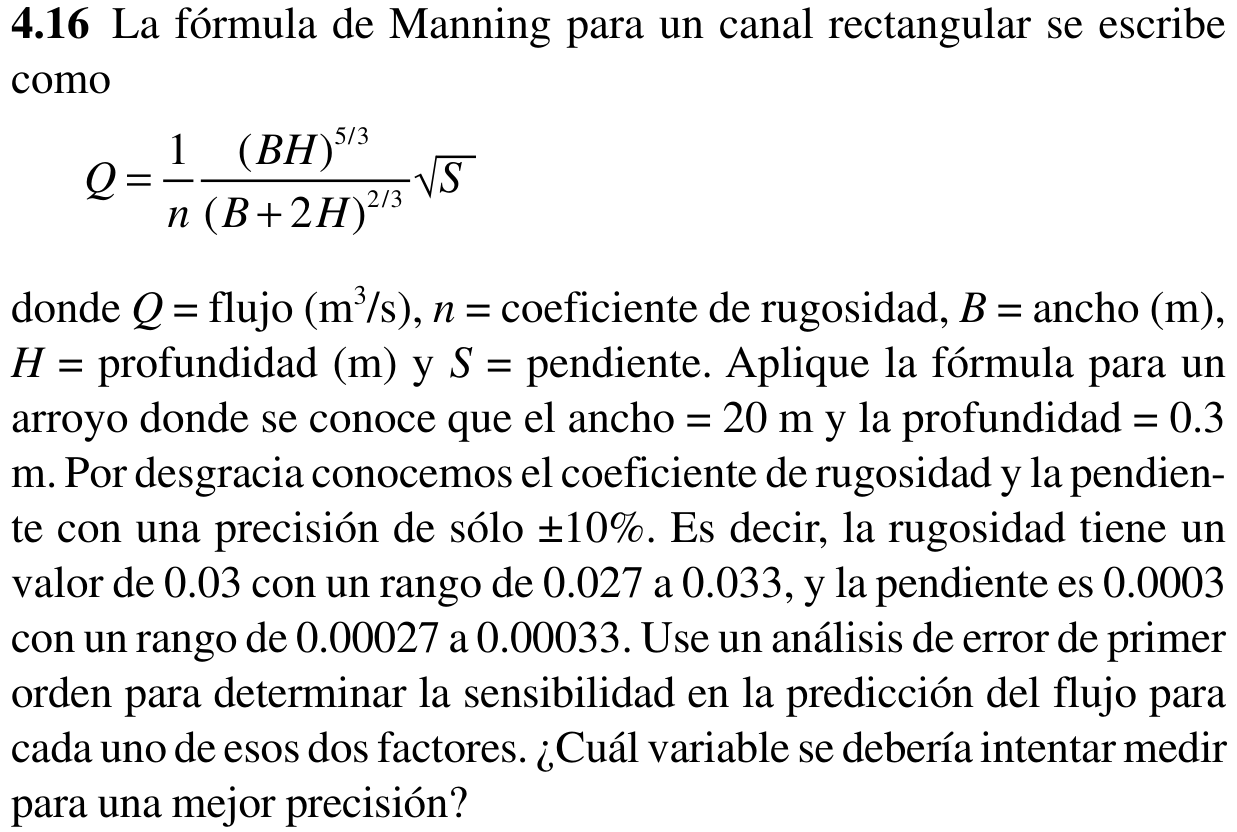

## Con calculadora

B=20;
H=0.3;
n_tilde=0.03;
dn=0.003;
S_tilde=0.0003;
dS=0.00003;

C=(B*H)^(5/3)/(B+2*H)^(2/3);
dQ=abs(-C*sqrt(S_tilde)/n_tilde^2)*dn+...
    abs(C/(2*sqrt(S_tilde)*n_tilde))*dS

dQ =    0.228316817443081


## Con Matlab

`Q=\frac{1}{n} \frac{ (BH)^{5/3} }{ (B+2H)^{2/3} } \sqrt{S}`


$$Q=\frac{1}{n} \frac{ (BH)^{5/3} }{ (B+2H)^{2/3} } \sqrt{S}$$


B=20; % ancho
H=0.3; % profundidad
n_tilde=0.03; % coef. rugosidad
dn=0.1*n_tilde; % 10% de incertidumbre
S_tilde=0.0003; % Pendiente
dS=0.1*S_tilde; % 10%

Calculando derivadas

syms n S
Q=(1/n)*(B*H)^(5/3)*sqrt(S)/(B+2*H)^(2/3) % expresion simb

$$Q = \frac{22305837491589496\,\sqrt{S}}{8460796772107973\,n}$$

dQ_n_sym=diff(Q,n) % expresion simb

$$dQ\_n\_sym = -\frac{22305837491589496\,\sqrt{S}}{8460796772107973\,n^{2}}$$

dQ_n=matlabFunction(dQ_n_sym) % función de matlab

dQ_n = function_handle with value:
    @(S,n)sqrt(S).*1.0./n.^2.*(-2.636375520225631)


dQ_S_sym=diff(Q,S)

$$dQ\_S\_sym = \frac{11152918745794748}{8460796772107973\,\sqrt{S}\,n}$$

dQ_S=matlabFunction(dQ_S_sym)

dQ_S = function_handle with value:
    @(S,n)(1.0./sqrt(S).*1.318187760112815)./n


La fórmula de propagación de errores

dQ=abs(dQ_n(S_tilde,n_tilde))*dn+...
    abs(dQ_S(S_tilde,n_tilde))*dS

dQ =    0.228316817443081
